# **Deep Learning in Quantitative Finance**

# Transformer Networks for Time Series Prediction

This demo is to show how to use transformer networks to model the daily price of stocks in MATLAB®. We will predict the price trend of three individual stocks. We will then set an initial value for investment in these stocks, and use the predicted time series values to trade.

New layers have been introduced in MATLAB R2023a and R2023b that allow for the introduction of transformer layers to network architectures developed using the Deep Network Designer. These new transformer layers are useful for performing timeseries prediction with financial data due to their ability to capture temporal dependencies and long-term dependencies in the data. The three layers that the following demo utilizes are the [`positionEmbeddingLayer`](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.positionembeddinglayer.html?s_tid=doc_ta)`,` [`selfAttentionLayer`](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.selfattentionlayer.html), and [`indexing1dLayer`](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.indexing1dlayer.html)`.`

- The `positionEmbeddingLayer` allows for the encoding of the position information of each element within the sequence. By incorporating position embedding, the model can learn to differentiate between different time steps and capture time dependencies within the data.

- The `selfAttentionLayer` allows for the model to weigh the importance of different elements within a sequence. This allows the model to capture the dependencies between all elements in the sequence and learn the relationships between them. Self-attention mechanisms are also effective at capturing long-term dependencies in the data, as it can establish connections between distant time steps, understanding patterns that may have a delayed impact on future outcomes.

- The `indexing1dLayer` allows for the extraction of data from the specified index of the input data. This allows the network to perform regression on the output of the `selfAttentionLayer`.

Requires: MATLAB R2023b, Deep Learning Toolbox™, Financial Toolbox™, Optimization Toolbox™, Statistics and Machine Learning Toolbox™

## **Import Data**

Retrieve the data for three individual stocks from the MAT-file. The date range for the stocks is from January 2000 to September 2023.

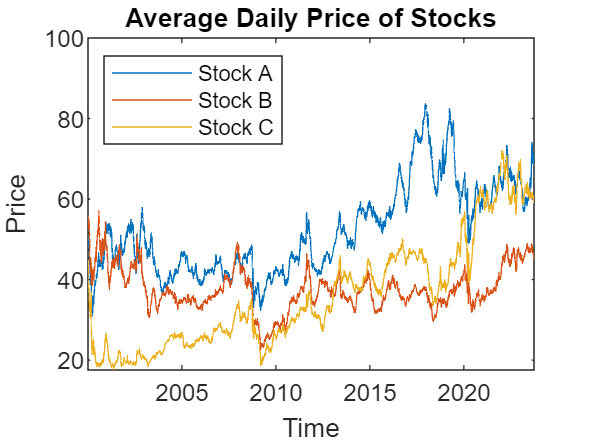

load transformer_demo.mat data varNames
plot(data, "dates", varNames)
legend(varNames, 'Location','Northwest')
title("Average Daily Price of Stocks")
ylabel("Price")
xlabel("Time")

## Data Preparation

Create indices for partitioning data into training set and testing set. The testing set will consist of the last three years in the dataset (2021-2023).

nTest = sum(year(data.dates) >= (year(data.dates(end))-2));
nTrain = height(data) - (nTest);
idxTrain = (1:nTrain)';
idxTest = (nTrain+1:height(data))';

**Step #1: Normalize the testing data **based on the training data using a local function defined at the end of this script.

[x1, mu1, sigma1] = standardizeByCol(data(idxTrain, :));
x2 = (data(idxTest, :) - repmat(mu1,nTest,1)) ./ repmat(sigma1,nTest,1);
xNorm = [x1; x2];

**Step #2: Create the feature variable**, consisting of the price of each stock over the past 30 days.

windowSize = 30;
nrows = size(xNorm,1) - windowSize;
features = cell(nrows, 1);

for row = 1:nrows
    features{row} = xNorm(row:windowSize+row-1,:).Variables';
end

**Step #3: Create the response variable**, consisting of the price of each stock after each rolling 30 day window.

response = xNorm(windowSize+1:end,:).Variables;
nFeatures = size(xNorm,2);

**Step #4: Split the features and response variables** into training and testing sets.

xTest = features(end-nTest+1:end,:);
yTest = response(end-nTest+1:end,:);

xTrain = features(1:end-nTest,:);
yTrain = response(1:end-nTest,:);

## Define Network Architecture

Specify the network architecture as a series of layers. This network architecture can be easily defined with the [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html).

numChannels = 3;
maxPosition = 256;
numHeads = 4;
numKeyChannels = numHeads*32;

layers = [sequenceInputLayer(numChannels,Name="input")

          %% Embed position information into layers
          positionEmbeddingLayer(numChannels,maxPosition,Name="pos-emb");
          additionLayer(2, Name="add")
          
          %% Self Attention Layer
          % "causal" — Prevent elements in position M from attending to elements in position N, where N is greater than M. Use this option for auto-regressive models.
          selfAttentionLayer(numHeads,numKeyChannels,'AttentionMask','causal') 
          selfAttentionLayer(numHeads,numKeyChannels)

          %% Last Layer
          indexing1dLayer("last")
          fullyConnectedLayer(numChannels)
          regressionLayer];

lgraph = layerGraph(layers);
lgraph = connectLayers(lgraph,"input","add/in2");

deepNetworkDesigner(lgraph)

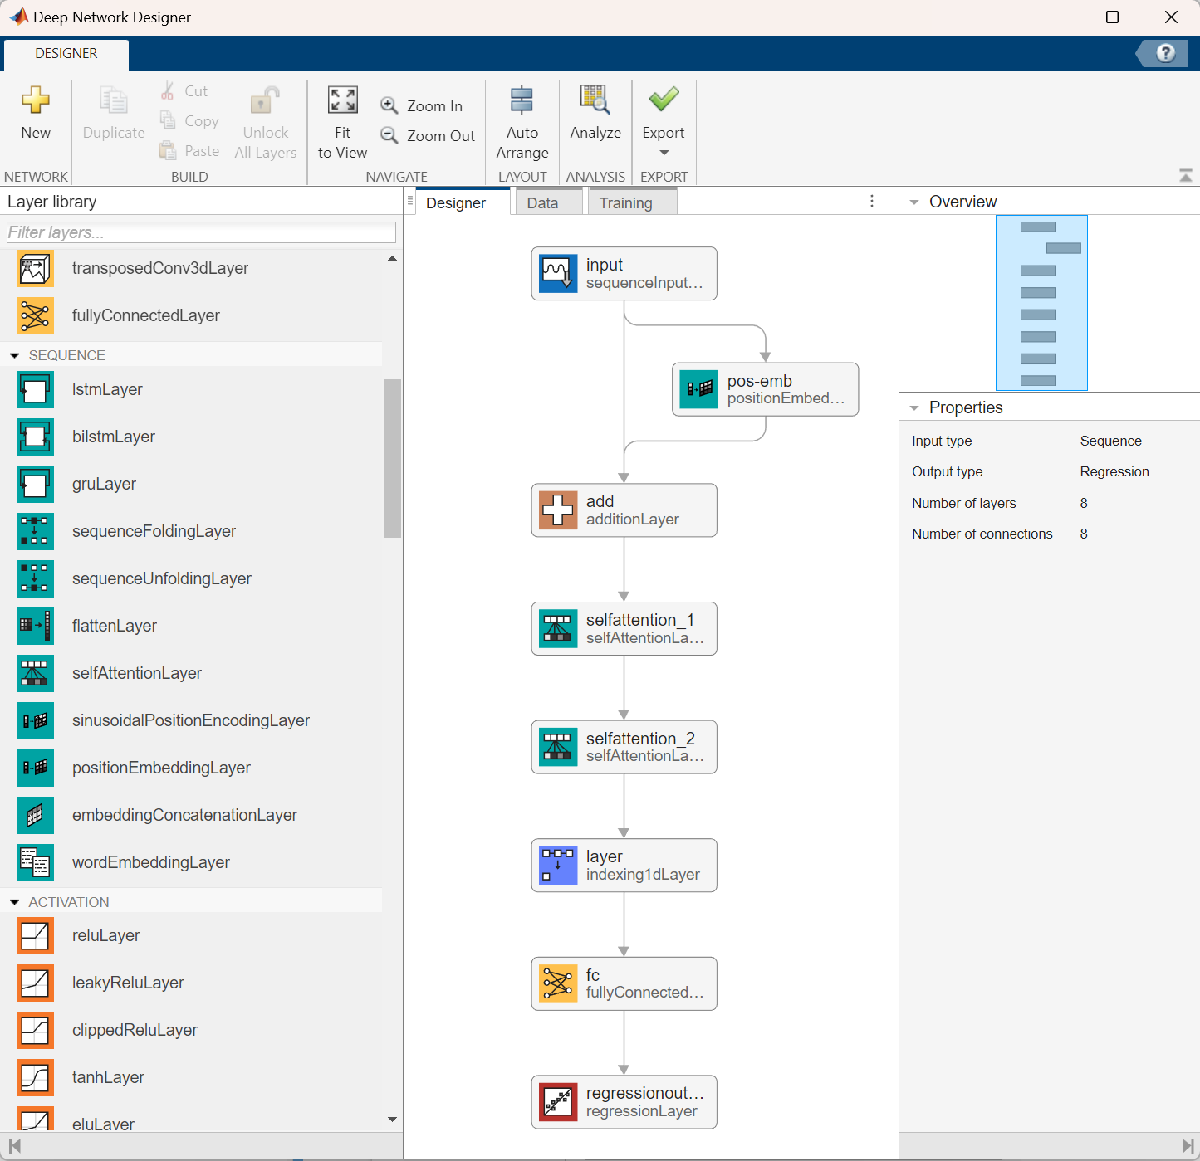

## Define Training Options for Transformer Model

Specify the training options for the model using the [`trainingOptions`](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function. There are many training options available depending on your specific use case. Using the [Experiment Manager](https://www.mathworks.com/help/deeplearning/ref/experimentmanager-app.html) (from the Deep Learning Toolbox) is an excellent way to test different network architectures as well as various network and training hyperparameters. Below is the output of an experiment to tune the input paramaters for the network architecture.

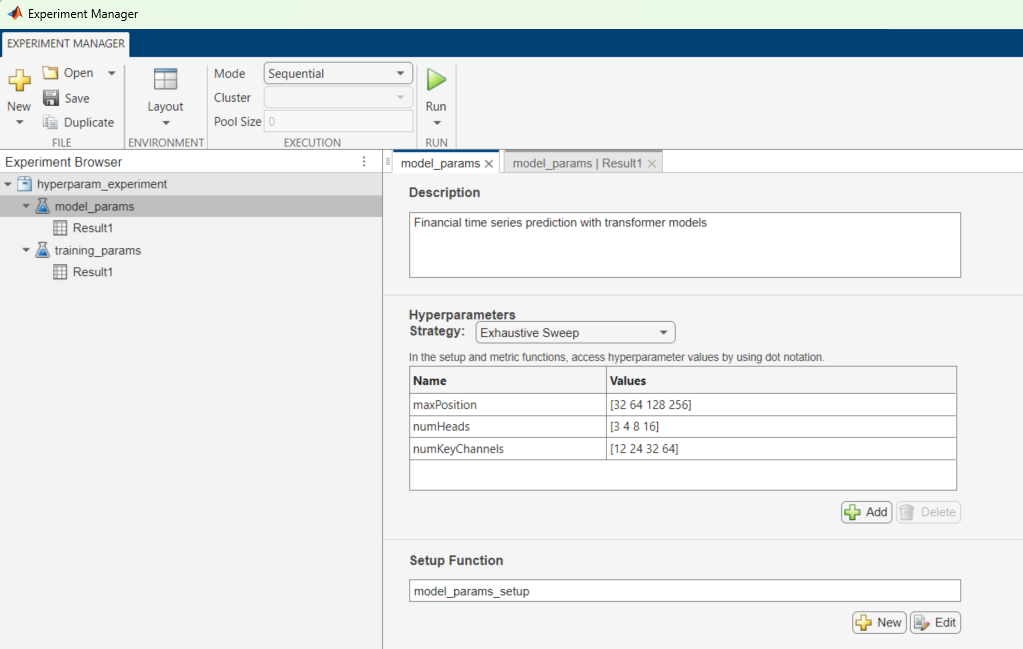

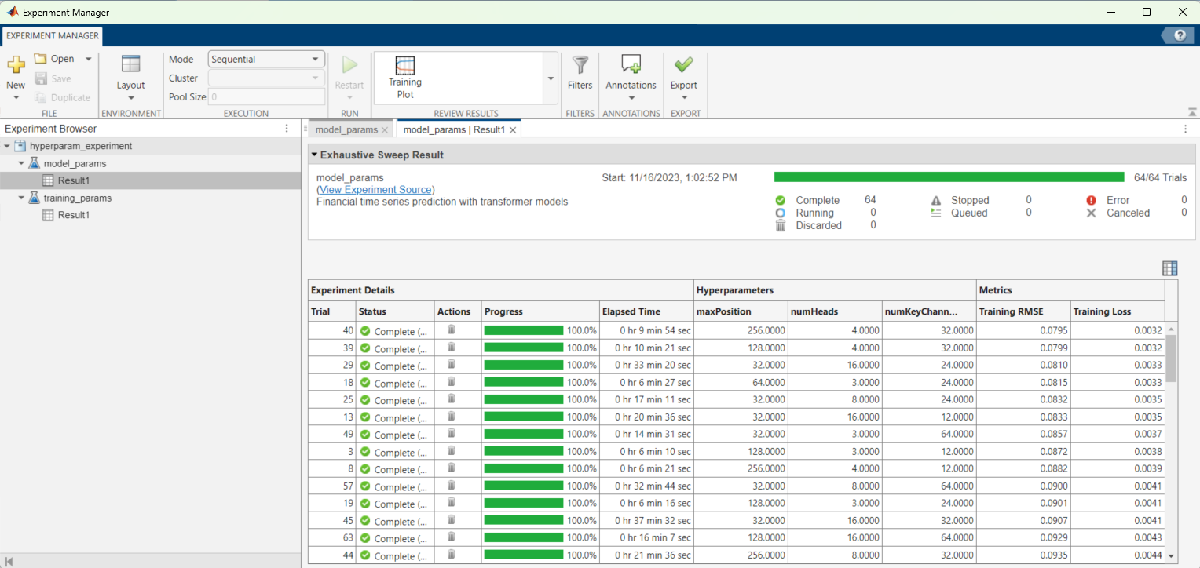

maxEpochs = 100;
miniBatchSize = 32;
learningRate = 0.001;
solver = 'adam';
shuffle = 'every-epoch';
gradientThreshold = 10;
executionEnvironment = "auto"; % chooses local GPU if available, otherwise CPU

options = trainingOptions(solver, ...
    'Plots','training-progress', ...
    'MaxEpochs', maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'Shuffle', shuffle, ...
    'InitialLearnRate', learningRate, ...
    'GradientThreshold', gradientThreshold, ...
    'ExecutionEnvironment', executionEnvironment);

## Train the Transformer Model

Utilizing the [`trainNetwork`](https://www.mathworks.com/help/deeplearning/ref/trainnetwork.html) function, we can utilize our cleaned data along with our network architecture and training options to train our model. To avoid waiting for the training and to save time, load the pretrained network by setting the `train` flag to `false`.

train = false;

if train
    net = trainNetwork(xTrain, yTrain, lgraph, options);
else
    load transformer_demo.mat net
end

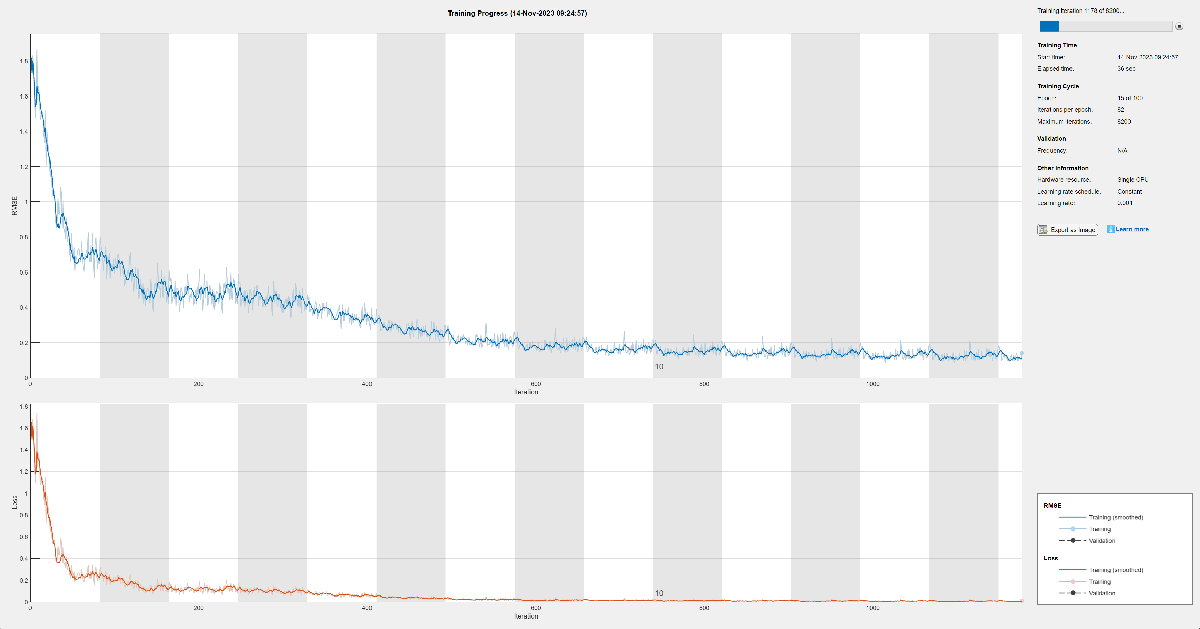

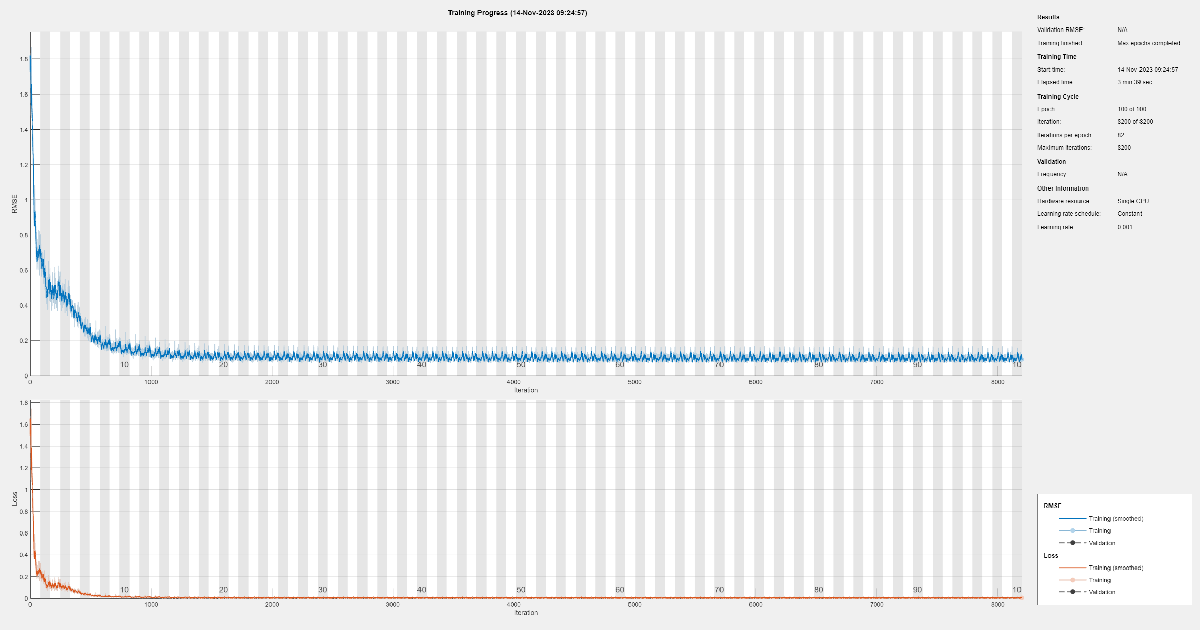

## Calculate Model Predictions

Using the trained network, predict the price of each stock after each rolling 30 day window from both the training and testing data sets.

yPredTrain = predict(net, xTrain);
yPredTest = predict(net, xTest);

Rescale the training and test variables after normalizing them for model training.

sigma = sigma1.Variables;
mu = mu1.Variables;

predictTrain = yPredTrain.*sigma + mu;
actualTrain = yTrain.*sigma + mu;
predictTest = yPredTest.*sigma + mu;
actualTest = yTest.*sigma + mu;

## Visualize Model Performance

Plot the predictions of the model on the training and testing data separately.

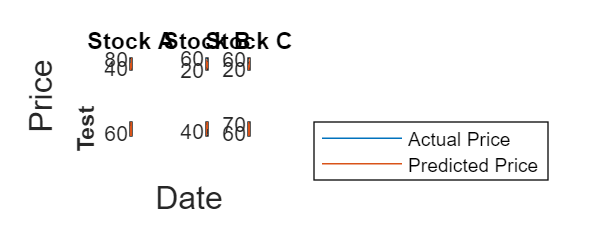

plotPrediction(actualTrain, predictTrain, actualTest, predictTest, data, windowSize, varNames)

Compute the percentage RMSE based on the average price of each stock for the training and testing data.

RMSE_Test = sqrt(mean((actualTest - predictTest).^2));
percent_RMSE_Test = RMSE_Test ./ mean(actualTest)

percent_RMSE_Test = 1×3 single row vector
    0.0100    0.0087    0.0106


## Backtest Model Performance on Testing Data

Now that we have predictions from our model, we can define some backtest strategies that will use these predictions of the model to define asset allocation strategies. We will begin by preparing the data to use [`backtestEngine`](https://www.mathworks.com/help/finance/backtestengine.html?s_tid=doc_ta) from the Financial Toolbox.

signalTimeTable = makeSignalTimeTable(data, nTest, predictTest);
pricesTimeTable = makePricesTimeTable(data, nTest, actualTest, varNames);

riskFreeRate = 0.01;
tradingCosts = 0.0001;

**We will now use **[`backtestStrategy`](https://www.mathworks.com/help/finance/backteststrategy.html)** to create four different trading strategies based on the signal indicators. **

These four trading strategies are defined using local functions at the end of this script, and implement the following strategies:

- Long Only: Invest all capital across the stocks with positive predicted return, **proporitional to the predicted return**

- Long Short: Invest capital across all the stocks, both positive and negative predicted return, **proportional to the predicted return**

- Best Bet: Invest all capital into the single asset with the highest predicted return

- Equal Weight: Rebalance invested capital every day with an equally-weighted allocation between the stocks

LongStrategy = backtestStrategy('LongOnly',@LongOnlyRebalanceFcn, ...
                                'TransactionCosts',tradingCosts, ...
                                'LookbackWindow',1);

LongShortStrategy = backtestStrategy('LongShort',@LongShortRebalanceFcn, ...
                                     'TransactionCosts',tradingCosts, ...
                                     'LookbackWindow',1);

BestBetStrategy = backtestStrategy('BestBet',@BestBetRebalanceFcn, ...
                                   'TransactionCosts',tradingCosts, ...
                                   'LookbackWindow',1);

equalWeightFcn = @(current_weights,prices,signal) ones(size(current_weights)) / numel(current_weights);
EqualWeightStrategy = backtestStrategy('EqualWeight',equalWeightFcn, ...
                                       'TransactionCosts',tradingCosts, ...
                                       'LookbackWindow',0);

%% Setup BackTest Engine
strategies = [LongStrategy LongShortStrategy BestBetStrategy EqualWeightStrategy];

bt = backtestEngine(strategies, 'RiskFreeRate', riskFreeRate);

**Run the stragies over the backtest range.**

bt = runBacktest(bt, pricesTimeTable, signalTimeTable);

**We can now use the **[`summary`](https://www.mathworks.com/help/finance/backtestengine.summary.html?s_tid=doc_ta)** and **[`equityCurve`](https://www.mathworks.com/help/finance/backtestengine.equitycurve.html?s_tid=doc_ta)** functions to summarize and plot the backtest results. **

summary(bt)

ans = 9×4 table
                        LongOnly     LongShort      BestBet      EqualWeight
                       __________    __________    __________    ___________

    TotalReturn           0.23226      0.076143      0.033911       0.13275 
    SharpeRatio          0.040275      0.014911     0.0051697      0.025377 
    Volatility          0.0072395     0.0055591     0.0081438     0.0064214 
    AverageTurnover      0.075312      0.078045      0.083942     0.0025756 
    MaxTurnover                 1       0.77689             1           0.5 
    AverageReturn      0.00033109    0.00012257    8.1804e-05    0.00020257 
    MaxDrawdown           0.16344       0.14036       0.23094       0.16619 
    AverageBuyCost 

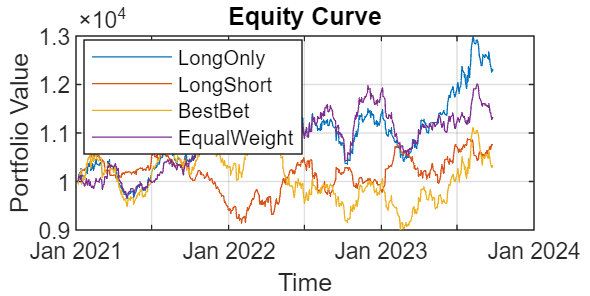

figure('Position', [1, 1, 800, 400])
equityCurve(bt)

## Local Functions

Local functions to normalize the data, create plots, and backtest strategy performance using model predictions.

function [data, mu, sigma] = standardizeByCol(data)
    [n, ~] = size(data);
    mu = mean(data, 1);
    sigma = std(data, 1);
    data = (data - repmat(mu,n,1)) ./ repmat(sigma,n,1);
end

function plotPrediction(actualTrain, predictTrain, actualTest, predictTest, data, windowSize, varNames)
    n = width(actualTrain);
    nTest = height(actualTest);
    train_dates = data(windowSize+1:end-nTest, :).dates;
    test_dates = data(end-nTest+1:end, :).dates;

    figure('Position', [1, 1, 1000, 400])
    t = tiledlayout(2,n);

    for i=1:n
        nexttile
        plot(train_dates, actualTrain(:, i));
        hold on
        plot(train_dates, predictTrain(:, i));
        hold off
        title(varNames(i))
        if i==1
            ylabel('Train','FontWeight','bold')
        end
    end
    
    for i=1:n
        nexttile
        plot(test_dates, actualTest(:, i));
        hold on
        plot(test_dates, predictTest(:, i));
        hold off
        if i==1
            ylabel('Test','FontWeight','bold')
        end
    end

    xlabel(t, "Date")
    ylabel(t, "Price")

    lg = legend(["Actual Price","Predicted Price"]);
    lg.Location = 'bestoutside';
end

function signal_timetable = makeSignalTimeTable(data, nTest, predictTest)
    prevDay = data(end-nTest:end-1, :);
    dates = data(end-nTest+1:end, :).dates;
    signals = predictTest - prevDay.Variables;
    signal_timetable = timetable(dates, signals);
end

function prices_timetable = makePricesTimeTable(data, nTest, actualTest, varNames)
    dates = data(end-nTest+1:end, :).dates;
    prices_timetable = timetable(dates, ...
        actualTest(:, 1), ...
        actualTest(:, 2), ...
        actualTest(:, 3), ...
        'VariableNames', varNames);
end

function new_weights = LongOnlyRebalanceFcn(current_weights, ~, signal_tt)
    signal = signal_tt.signals(end, :);
    
    if any(0 < signal)
        signal(signal < 0) = 0;
        new_weights = signal / sum(signal);
    else
        new_weights = zeros(size(current_weights));
    end
end

function new_weights = LongShortRebalanceFcn(current_weights, ~, signal_tt)
    signal = signal_tt.signals(end, :);
    abssum = sum(abs(signal));
    
    if 0 < abssum
        new_weights = signal / abssum;
    else
        new_weights = zeros(size(current_weights));
    end
end

function new_weights = BestBetRebalanceFcn(current_weights, ~, signal_tt)
    signal = signal_tt.signals(end, :);
    new_weights = zeros(size(current_weights));
    new_weights(signal == max(signal)) = 1;
end

Copyright 2023 The MathWorks, Inc.